# Méthode Muttin version 1.0.0

## Parametre

phi=5;
lambda=1;
flux_chaleur=-phi/lambda;
h=1; % pas
Tini=20; % temperature initiale du contour (mur)
Trad=80; % temperature initiale du contour (au niveau du radiateur)


## Vecteur C

c'est des cste à droite de l'éq

C=zeros(29,1);
C(1,1)=h^2*flux_chaleur-Tini-Trad;
C(5,1)=h^2*flux_chaleur-Trad;
C(9,1)=h^2*flux_chaleur-Trad;
C([2:3 8 13 14 16 22 24:28],1)=-Tini;
C([4 15 23 29],1)=-2*Tini;


## Matrice A

c'est la grosse matrice des coefs

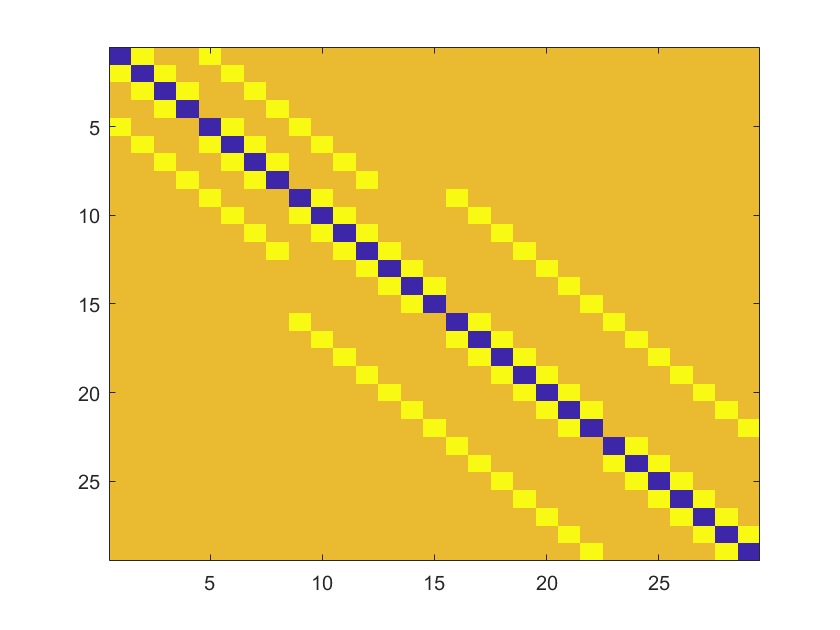

A1=[diag(-4*ones(4,1))+diag(ones(3,1),-1)+diag(ones(3,1),1)  diag(ones(4,1))  zeros(4,21)];
A2=[diag(ones(4,1)) diag(-4*ones(4,1))+diag(ones(3,1),-1)+diag(ones(3,1),1)  diag(ones(4,1)) zeros(4,3) zeros(4,14)];
temp=[diag(ones(4,1));zeros(3,4)];
A3=[zeros(7,4) temp diag(-4*ones(7,1))+diag(ones(6,1),-1)+diag(ones(6,1),1) diag(ones(7,1)) zeros(7)];
A4=[zeros(7,8) diag(ones(7,1)) diag(-4*ones(7,1))+diag(ones(6,1),-1)+diag(ones(6,1),1) diag(ones(7,1))];
A5=[zeros(7,15) diag(ones(7,1)) diag(-4*ones(7,1))+diag(ones(6,1),-1)+diag(ones(6,1),1)];
A=[A1;A2;A3;A4;A5];
imagesc(A)

## Tvec

c'est le  vecteur de T, la température que l'on cherche

On a A*Tvec=C

donc Tvec=A' * C

Tvec=A\C

Tvec =    48.8887
   33.8756
   26.7786
   22.8530
   56.6792
   39.8352
   30.3859
   24.6334
   52.9930
   38.4002


## Graphe

Décomposer vecteur Tvec à une matice T

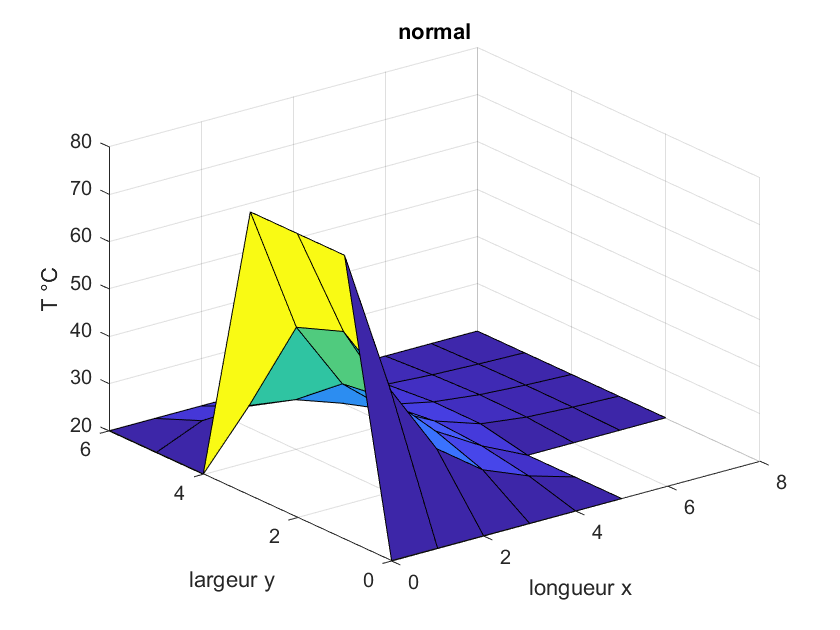

T=zeros(7,9);
T(1,1:6)=Tini;
T(3,6:9)=Tini;
T(7,1:9)=Tini;
T(1:7,1)=Tini;
T(2:4,1)=Trad;
T(1:3,6)=Tini;
T(3:7,9)=Tini;
T(2,2:5)=Tvec(1:4);
T(3,2:5)=Tvec(5:8);
T(4,2:8)=Tvec(9:15);
T(5,2:8)=Tvec(16:22);
T(6,2:8)=Tvec(23:29);
for i=1:7
    for j=1:9
        if T(i,j)==0
            T(i,j)=nan;
        end
    end
end
% graphe normal
[X,Y]=meshgrid(0:h:8,0:h:6);
figure(1)
surf(X,Y,T)
xlabel('longueur x')
ylabel('largeur y')
zlabel('T °C')
title('normal')

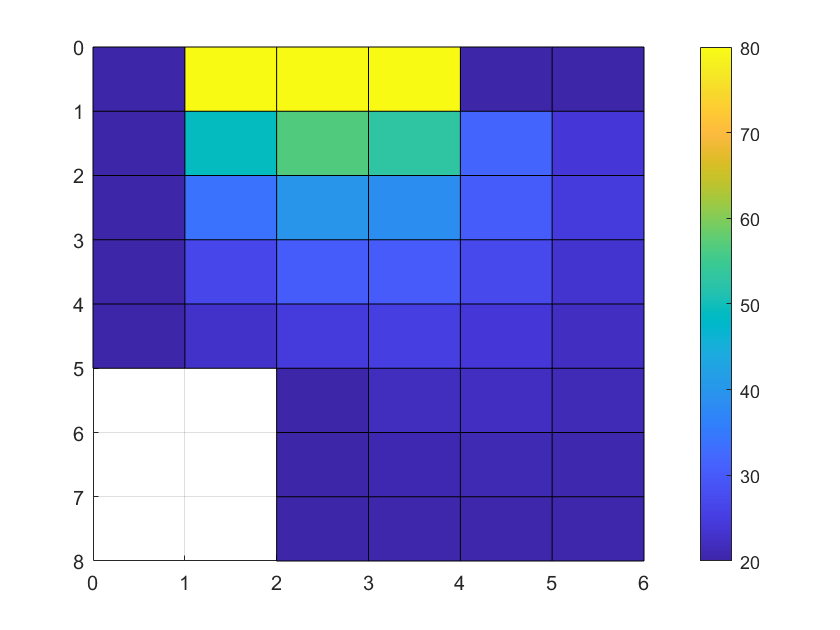


figure(6)
surf(X,Y,T)
view([90,90])
colorbar

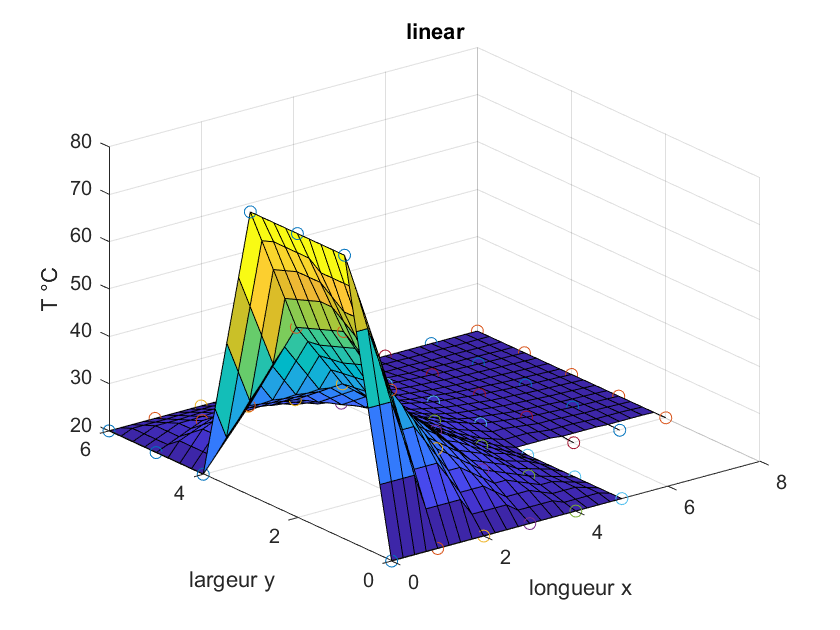

% interpolation
figure(2)
[xq,yq] = meshgrid(0:.25:8, 0:.25:6);
vq = griddata(X,Y,T,xq,yq,'linear');
surf(xq,yq,vq)
xlabel('longueur x')
ylabel('largeur y')
zlabel('T °C')
title('linear')
hold on
plot3(X,Y,T,'o')

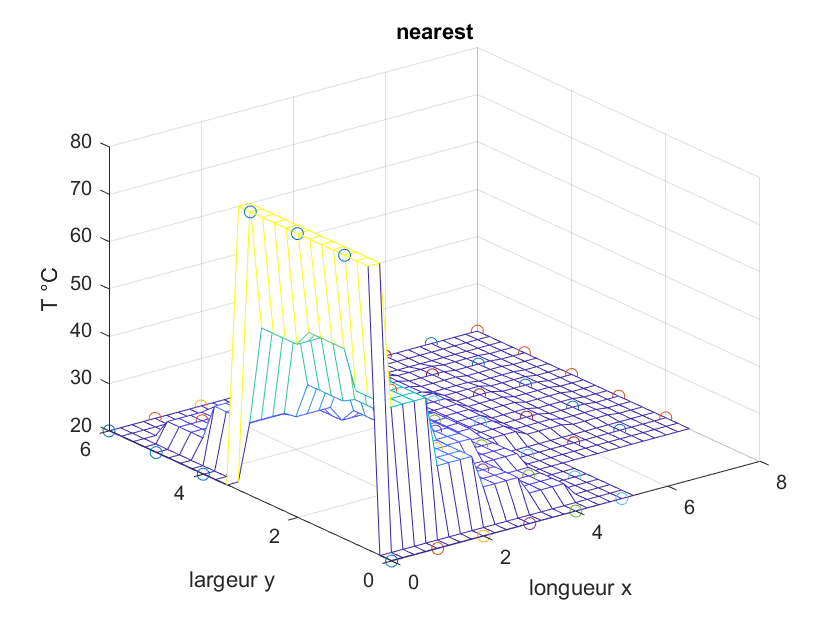


figure(3)
vq = griddata(X,Y,T,xq,yq,'nearest');
mesh(xq,yq,vq)
xlabel('longueur x')
ylabel('largeur y')
zlabel('T °C')
title('nearest')
hold on
plot3(X,Y,T,'o')

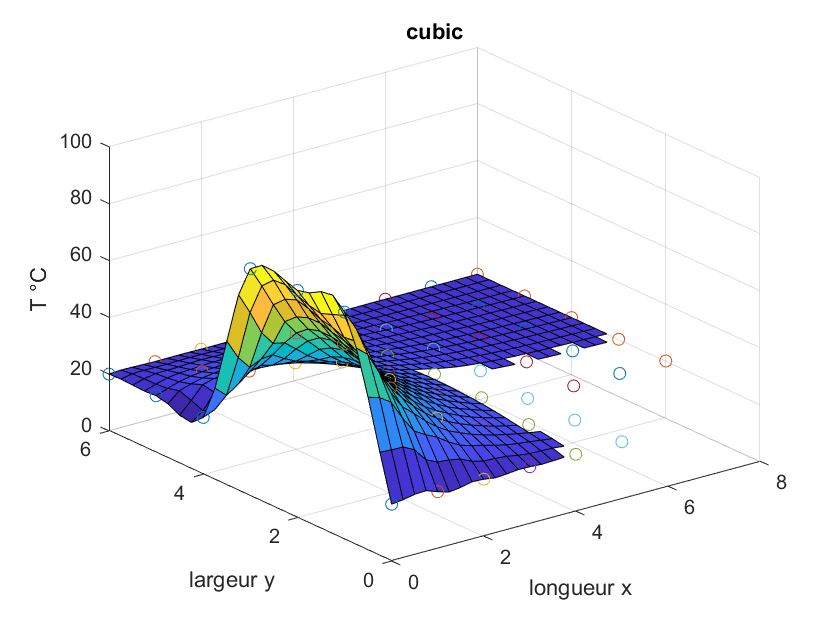

figure(4)
vq = griddata(X,Y,T,xq,yq,'cubic');
surf(xq,yq,vq)
xlabel('longueur x')
ylabel('largeur y')
zlabel('T °C')
title('cubic')
hold on
plot3(X,Y,T,'o')

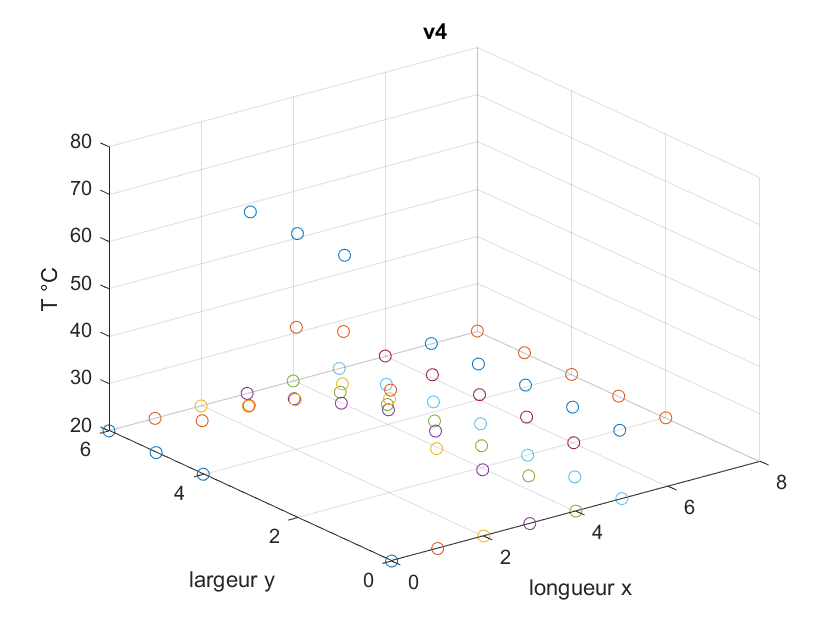

figure(5)
vq = griddata(X,Y,T,xq,yq,'v4');
surf(xq,yq,vq)
xlabel('longueur x')
ylabel('largeur y')
zlabel('T °C')
title('v4')
hold on
plot3(X,Y,T,'o')